addpath(genpath('./'));

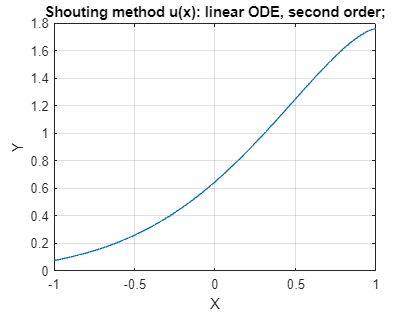

% case 2

a = -1;
b = 1;

h = 0.02;
n = (b - a) / h;

kernel = @(x)(1);
p = @(x)(acos(x));
rightFunc = @(x)(1 + x*sin(1 + x^2));

[d1, d2, d3, d4, d5, d6] = deal(1, 1, 1, 1, 17, 1);

[X, Y] = linearBVP2shoutingSolver(kernel, p, rightFunc, d1, d2, d3, d4, d5, d6, a, b, n);

% ONLY FOR THIS EXAMPLE
Y = real(Y); % there is some stupid 10^(-9)i

[Y1, Y2] = deal(Y(1, :), Y(2, :));

complexPlot(X, Y1, "Shouting method u(x): linear ODE, second order;");

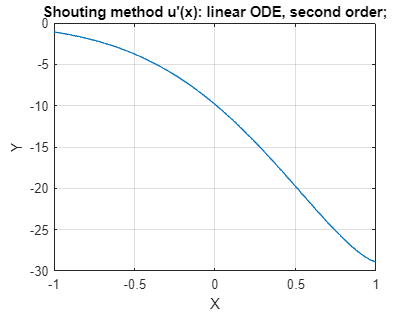

complexPlot(X, Y2, "Shouting method u'(x): linear ODE, second order;");

 
% let's check
disp(d1 * Y(2, 1) + d2 * Y(1, 1) + d3);

     0



disp(d4 * Y(2, end) + d5 * Y(1, end) - d6);

     0



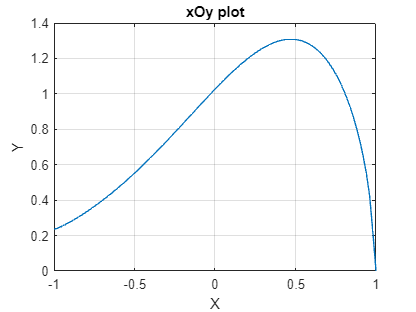



Z = [];
for i=1:length(X) - 1
    Z(i) = (Y1(i + 1) - Y1(i)) / (X(i + 1) - X(i));
end
Z(end + 1) = 0;
complexPlot(X, Z);